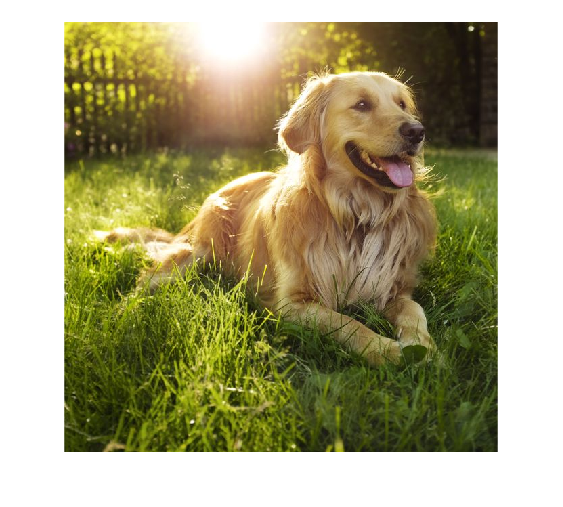

img = imread("img.jpg");
imshow(img);

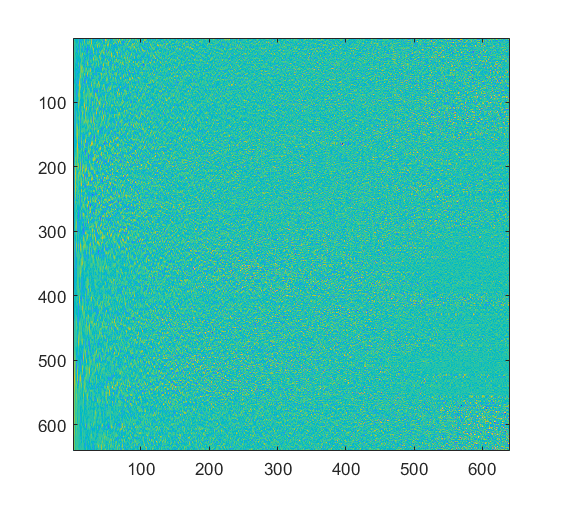


%img = rgb2hsv(img);

R = double(img(:,:,1));
G = double(img(:,:,2));
B = double(img(:,:,3));

[U,S,V] = svd(R);
% U = U + 0.02;
% V = V + 0.02;
%V(500:640)  = 0;
% S(S < 20) = 0;
%V = V + imnoise(V,"salt & pepper",0.01)./10;
imagesc(V);

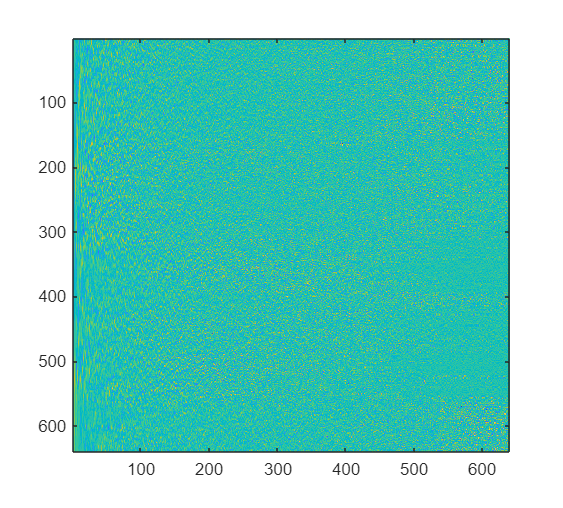

V = rescale(V,-0.5,0.5);
imagesc(V);

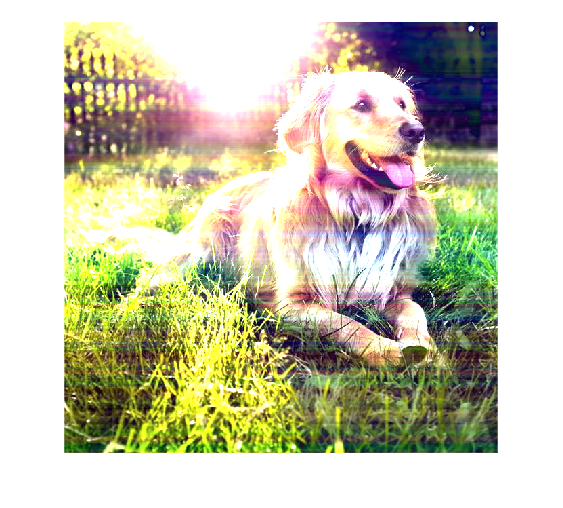

R = U*S*V';
R=abs(R);


[U,S,V] = svd(G);
%U = U + 0.02;
%V(500:640)  = 0;
%S(S < 100) = 0;
%V = V + imnoise(V,"salt & pepper",0.01)./10;
V = rescale(V,-0.5,0.5);
G = U*S*V';
G=abs(G);

[U,S,V] = svd(B);
%U = U + 0.02;
%V(500:640)  = 0;
%S(S < 3) = 0;
%V = V + imnoise(U,"salt & pepper",0.01)./10;
V = rescale(V,-0.5,0.5);
B = U*S*V';

%I = uint8(hsv2rgb(cat(3,R,G,B))*255);
I =uint8(cat(3,R,G,B));
imshow(I)

img = imread("img.jpg");
imshow(img)

[IND,map] = rgb2ind(img,256);


[U,S,V] = svd(double(IND));

%U = U + 0.00008;
%V = V ./ 0.998;
%V(500:640)  = 0;
S(S < 50) = 0;
IND = uint8(U*S*V');


I = ind2rgb(IND,map);
imshow(I)


